data = readtable("finchData.csv")

data = 651×5 table
    Band     Species      BeakLength    BeakDepth    Year
    ____    __________    __________    _________    ____

      2     {'fortis'}        9.4            8       1975
      9     {'fortis'}        9.2          8.3       1975
     12     {'fortis'}        9.5          7.5       1975
     15     {'fortis'}        9.5            8       1975
    305     {'fortis'}       11.5          9.9       1975
    307     {'fortis'}       11.1          8.6       1975
    308     {'fortis'}        9.9          8.4       1975
    309     {'fortis'}       11.5          9.8       1975
    311     {'fortis'}       10.8          9.2       1975
    312     {'fortis'}       11.3            9       1975
    313     {'fortis'}       11.5          9.5       1975
    314     {'fortis'}       11.5          8.9       197

summary(data)

Variables:

    Band: 651×1 double

        Values:

            Min            2  
            Median       923  
            Max        22000  

    Species: 651×1 cell array of character vectors

    BeakLength: 651×1 double

        Values:

            Min          8.7  
            Median        11  
            Max        15.94  

    BeakDepth: 651×1 double

        Values:

            Min          7.2  
            Median         9  
            Max         11.1  

    Year: 651×1 double

        Values:

            Min         1975  
            Median      1975  
            Max         2012  




data.Species = categorical(data.Species)

data = 651×5 table
    Band    Species    BeakLength    BeakDepth    Year
    ____    _______    __________    _________    ____

      2     fortis         9.4            8       1975
      9     fortis         9.2          8.3       1975
     12     fortis         9.5          7.5       1975
     15     fortis         9.5            8       1975
    305     fortis        11.5          9.9       1975
    307     fortis        11.1          8.6       1975
    308     fortis         9.9          8.4       1975
    309     fortis        11.5          9.8       1975
    311     fortis        10.8          9.2       1975
    312     fortis        11.3            9       1975
    313     fortis        11.5          9.5       1975
    314     fortis        11.5          8.9       1975
    315     fortis         9.7          

summary(data.Species)

     fortis        437 
     scandens      214 



data.Year = categorical(data.Year)

data = 651×5 table
    Band    Species    BeakLength    BeakDepth    Year
    ____    _______    __________    _________    ____

      2     fortis         9.4            8       1975
      9     fortis         9.2          8.3       1975
     12     fortis         9.5          7.5       1975
     15     fortis         9.5            8       1975
    305     fortis        11.5          9.9       1975
    307     fortis        11.1          8.6       1975
    308     fortis         9.9          8.4       1975
    309     fortis        11.5          9.8       1975
    311     fortis        10.8          9.2       1975
    312     fortis        11.3            9       1975
    313     fortis        11.5          9.5       1975
    314     fortis        11.5          8.9       1975
    315     fortis         9.7          

summary(data.Year)

     1975      403 
     2012      248 



idxScandens = data.Species == "scandens"

idxScandens = 651×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



scandens = data(idxScandens, :)

scandens = 214×5 table
    Band    Species     BeakLength    BeakDepth    Year
    ____    ________    __________    _________    ____

    302     scandens       13.9          8.4       1975
    304     scandens         14          8.8       1975
    306     scandens       12.9          8.4       1975
    310     scandens       13.5            8       1975
    317     scandens       12.9          7.9       1975
    318     scandens       14.6          8.9       1975
    319     scandens         13          8.6       1975
    322     scandens       14.2          8.5       1975
    325     scandens         14          8.9       1975
    327     scandens       14.2          9.1       1975
    351     scandens       13.1          8.6       1975
    353     scandens       15.1          9.8       1975
    357     scandens  

summary(scandens)

Variables:

    Band: 214×1 double

        Values:

            Min          302  
            Median     19459  
            Max        21347  

    Species: 214×1 categorical

        Values:

            fortis          0   
            scandens      214   

    BeakLength: 214×1 double

        Values:

            Min         11.4  
            Median      13.7  
            Max        15.94  

    BeakDepth: 214×1 double

        Values:

            Min          7.7  
            Median     9.075  
            Max           11  

    Year: 214×1 categorical

        Values:

            1975       87   
            2012      127   



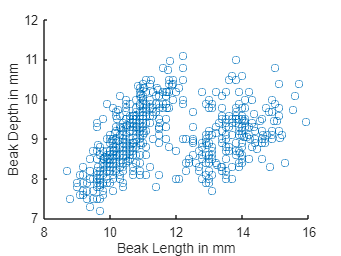

scandens = data(data.Species == "scandens",:);
fortis = data(data.Species == "fortis",:);

scatter(data.BeakLength, data.BeakDepth)
xlabel("Beak Length in mm")
ylabel("Beak Depth in mm")

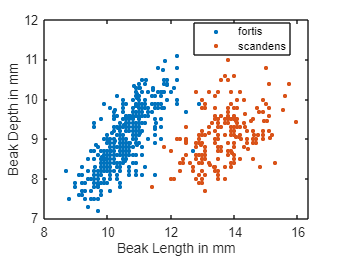

gscatter(data.BeakLength, data.BeakDepth, data.Species)
xlabel("Beak Length in mm")
ylabel("Beak Depth in mm")

data = readtable("finchData.csv");
data.Species = categorical(data.Species);
data.Year = categorical(data.Year);
scandens = data(data.Species == "scandens",:)

scandens = 214×5 table
    Band    Species     BeakLength    BeakDepth    Year
    ____    ________    __________    _________    ____

    302     scandens       13.9          8.4       1975
    304     scandens         14          8.8       1975
    306     scandens       12.9          8.4       1975
    310     scandens       13.5            8       1975
    317     scandens       12.9          7.9       1975
    318     scandens       14.6          8.9       1975
    319     scandens         13          8.6       1975
    322     scandens       14.2          8.5       1975
    325     scandens         14          8.9       1975
    327     scandens       14.2          9.1       1975
    351     scandens       13.1          8.6       1975
    353     scandens       15.1          9.8       1975
    357     scandens  

fortis = data(data.Species == "fortis",:)

fortis = 437×5 table
    Band    Species    BeakLength    BeakDepth    Year
    ____    _______    __________    _________    ____

      2     fortis         9.4            8       1975
      9     fortis         9.2          8.3       1975
     12     fortis         9.5          7.5       1975
     15     fortis         9.5            8       1975
    305     fortis        11.5          9.9       1975
    307     fortis        11.1          8.6       1975
    308     fortis         9.9          8.4       1975
    309     fortis        11.5          9.8       1975
    311     fortis        10.8          9.2       1975
    312     fortis        11.3            9       1975
    313     fortis        11.5          9.5       1975
    314     fortis        11.5          8.9       1975
    315     fortis         9.7        

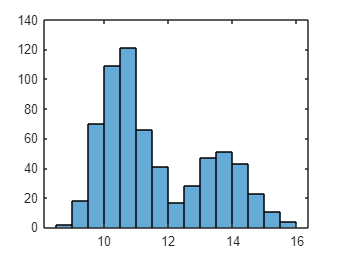

histogram(data.BeakLength)

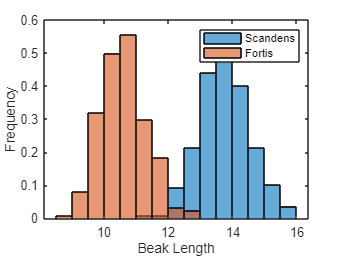



histogram(scandens.BeakLength, "BinWidth", 0.5, "Normalization","pdf")
hold on
histogram(fortis.BeakLength, "BinWidth", 0.5, "Normalization","pdf")
hold off
legend("Scandens", "Fortis")
xlabel("Beak Length")
ylabel("Frequency")

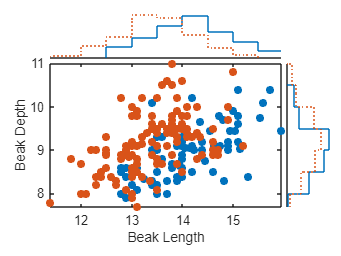



scatterhistogram(scandens.BeakLength, scandens.BeakDepth, "GroupData",scandens.Year)
xlabel("Beak Length")
ylabel("Beak Depth")

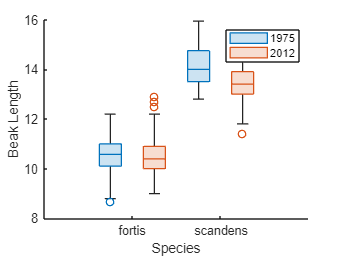


boxchart(data.Species, data.BeakLength, "GroupByColor",data.Year)
legend
xlabel("Species")
ylabel("Beak Length")


sLength1975 = scandens.BeakLength(scandens.Year=="1975");
sLength2012 = scandens.BeakLength(scandens.Year=="2012");

m1975 = mean(sLength1975)

m1975 = 14.1209

med1975 = median(sLength1975)

med1975 = 14

m2012 = mean(sLength2012)

m2012 = 13.4210

med2012 = median(sLength2012)

med2012 = 13.4000

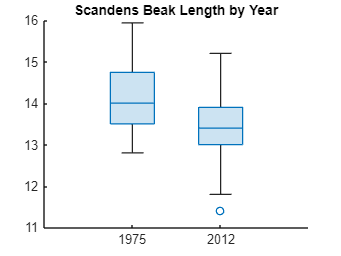


sLength1975 = scandens.BeakLength(scandens.Year=="1975");
sLength2012 = scandens.BeakLength(scandens.Year=="2012");
boxchart(scandens.Year,scandens.BeakLength)
title("Scandens Beak Length by Year")


s1975 = std(sLength1975)

s1975 = 0.7548

s2012 = std(sLength2012)

s2012 = 0.7204


iqr1975 = iqr(sLength1975)

iqr1975 = 1.2450

iqr2012 = iqr(sLength2012)

iqr2012 = 0.9000


r1975 = range(sLength1975)

r1975 = 3.1400

r2012 = range(sLength2012)

r2012 = 3.8000

skew1975 = skewness(sLength1975)

skew1975 = 0.1867

skew2012 = skewness(sLength2012)

skew2012 = -0.0508

kurt1975 = kurtosis(sLength1975)

kurt1975 = 2.3568

kurt2012 = kurtosis(sLength2012)

kurt2012 = 2.8759

% Compute group summary
newTable = groupsummary(scandens,"Year")

newTable = 2×2 table
    Year    GroupCount
    ____    __________

    1975        87    
    2012       127    



m1975 = mean(sLength1975)

m1975 = 14.1209

s1975 = std(sLength1975)

s1975 = 0.7548

x = randn(10000, 1)

x =     0.2392
    1.1967
    0.3499
   -0.8978
    0.4331
    1.2105
   -0.7500
    0.6037
    1.5864
   -0.2859


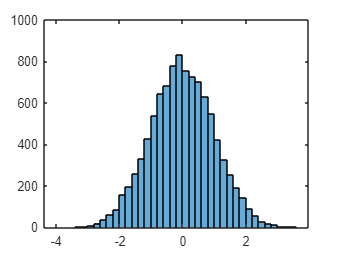

histogram(x)

x1975 = normrnd(m1975, s1975, [87,1])

x1975 =    14.7532
   14.5841
   14.6929
   14.8267
   14.4421
   13.5900
   14.8724
   14.4285
   13.8482
   13.7662


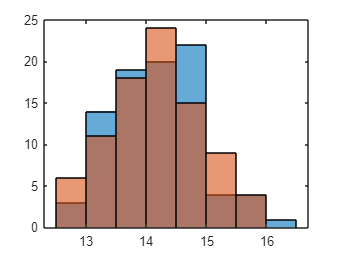

histogram(x1975)
hold on
histogram(sLength1975)
hold off



m2012 = mean(sLength2012)

m2012 = 13.4210

s2012 = std(sLength2012)

s2012 = 0.7204

x = randn(10000, 1)

x =     0.6471
    0.0057
    1.3262
   -1.2807
   -1.4889
    0.0406
    0.1823
    0.2075
    0.2569
   -0.6136


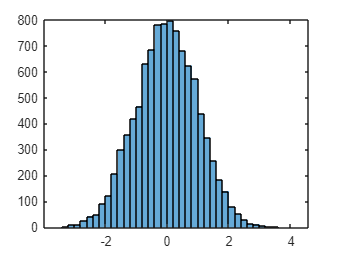

histogram(x)

x2012 = normrnd(m2012, s2012, [87,1])

x2012 =    13.3385
   12.7330
   12.4098
   14.9109
   13.8577
   13.5356
   14.1737
   13.1765
   13.1934
   13.2335


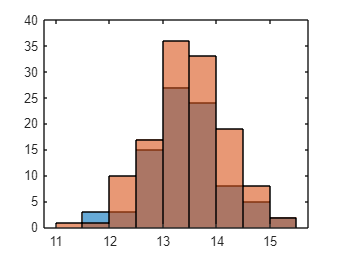

histogram(x2012)
hold on
histogram(sLength2012)
hold off

x = min(sLength1975):0.1:max(sLength1975)

x =    12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000   15.0000   15.1000   15.2000   15.3000   15.4000   15.5000   15.6000   15.7000   15.8000   15.9000



pdf1975 = normpdf(x, m1975, s1975)

pdf1975 =     0.1143    0.1429    0.1755    0.2117    0.2511    0.2926    0.3350    0.3768    0.4165    0.4524    0.4829    0.5064    0.5218    0.5283    0.5257    0.5139    0.4936    0.4659    0.4321    0.3938    0.3526    0.3103    0.2682    0.2279    0.1902    0.1560    0.1257    0.0996    0.0775    0.0592    0.0445    0.0329


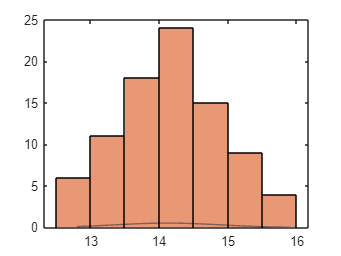


plot(x, pdf1975)
hold on
histogram(sLength1975)
hold off


cdf1975 = normcdf(x, m1975, s1975)

cdf1975 =     0.0401    0.0529    0.0688    0.0881    0.1112    0.1384    0.1698    0.2054    0.2450    0.2885    0.3354    0.3849    0.4364    0.4889    0.5417    0.5938    0.6442    0.6922    0.7372    0.7785    0.8159    0.8490    0.8779    0.9027    0.9236    0.9409    0.9549    0.9662    0.9750    0.9818    0.9869    0.9908


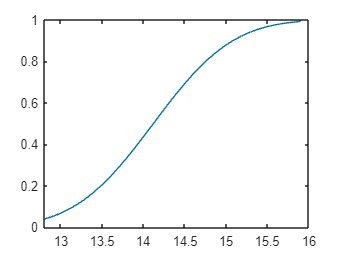

plot(x, cdf1975)

pdist1975 = fitdist(sLength1975, "Normal")

pdist1975 =   NormalDistribution

  Normal distribution
       mu =  14.1209   [13.9601, 14.2818]
    sigma = 0.754789   [0.656891, 0.887247]



plot(pdist1975)

mu1975 = pdist1975.mu

mu1975 = 14.1209

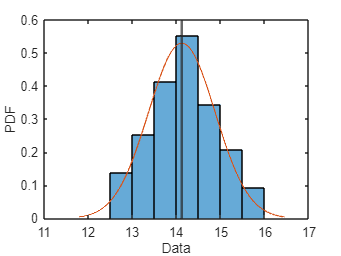

xline(mu1975, "LineWidth", 2)

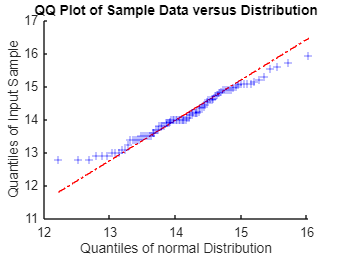


qqplot(sLength1975,pdist1975)

# Test for Population Difference

Let's set up the test for the difference in population means.

## State hypotheses

Without any evidence or outside information, there's no reason to assume the beak lengths have changed. Thus, the null and alternative hypothesis in this case are the following:

- ***H******0***: The average beak length in 1975 is the same as the average beak length in 2012.

- ***H******1***: The average beak length in 1975 is NOT the same as the average beak length in 2012.

h = ttest2(sLength1975, sLength2012)

h = 1

interpretResult(h)

Reject null hypothesis


# One-Sided Test for Population Difference

The previous test returned a `1`, meaning there is enough evidence to reject the null hypothesis (beak lengths are the same), in favor of the alternative hypothesis (beak lengths have changed). By default, the *t*-test tests whether there's any difference, in either direction. However, the data suggests something more specific, which is that the beak lengths are getting shorter. Can we test this specific question?

Yes! This is known as a one-sided (or one-tailed) *t*-test. You can call it by specifying the `"Tail"` property in `ttest`. Let's set up this test.

## State hypotheses

The default behavior includes no change in the beak length, while what we are trying to find is a decrease in the average beak length. With this information, you can set up the null and alternative hypothesis the following way:

- ***H******0***: The average beak length in 1975 is less than or equal than the average beak length in 2012.

- ***H******1***: The average beak length in 1975 is greater than the average beak length in 2012.

## Select and conduct test

You can use a right-tailed test to determine if the mean of `pop1` is greater than the mean of `pop2` by using the following notation:

`h` `=` `ttest2``(``pop1``,``pop2``,``"Tail"``,``"right"``)`

## Interpret and communicate results

Finally, you need to interpret the result from your test.

- **h=1**: Reject ***H******0***, meaning there is not enough evidence suggesting that the average beak length has decreased.

- **h=0**: Fail to reject ***H******0***, meaning there is evidence suggesting that the average beak length has decreased.

hTail = ttest2(sLength1975, sLength2012,"Tail","right")

hTail = 1

interpretResult(hTail)

Reject null hypothesis


# Test for Normality

You can use hypothesis testing to check if your data follows a normal distribution. Let's set up this test.

## State hypotheses

Most of the data tends to be normal, therefore, the null and alternative hypothesis in this case are the following:

- ***H******0***: The data follows a normal distribution.

- ***H******1***: The data does not follow a normal distribution.

## Select and conduct test

There are several tests you can use to test for normality. These include:

**Test Name****Function**

Jarque-Bera[`jbtest`](https://www.mathworks.com/help/stats/jbtest.html)

Lilliefors[`lillietest`](https://www.mathworks.com/help/stats/lillietest.html)

Anderson-Darling[`adtest`](https://www.mathworks.com/help/stats/adtest.html)

Chi-square goodness-of-fit[`chi2gof`](https://www.mathworks.com/help/stats/chi2gof.html)

Kolmogorov-Smirnov[`kstest`](https://www.mathworks.com/help/stats/kstest.html)

    All these functions use the syntax:

 `h` `=` `jbtest``(``data``)`

## Interpret and communicate results

Finally, you need to interpret the result from your test.

- **h=1**: Reject the null hypothesis, suggesting the data does not follow a normal distribution.

- **h=0**: Fail to reject the null hypothesis, suggesting the data does follow a normal distribution.

h1975 = jbtest(sLength1975)

h1975 = 0

h2012 = jbtest(sLength2012)

h2012 = 0


interpretResult(h1975)

Fail to reject null hypothesis


interpretResult(h2012)

Fail to reject null hypothesis



hLillie1975 = lillietest(sLength1975)

hLillie1975 = 0

hLillie2012 = lillietest(sLength2012)

hLillie2012 = 0


interpretResult(hLillie1975)

Fail to reject null hypothesis


interpretResult(hLillie2012)

Fail to reject null hypothesis


function interpretResult(h)
    if h == 1
        disp("Reject null hypothesis")
    else
        disp("Fail to reject null hypothesis")
    end
end